clearvars
close all
clc

%% Change directory
% Get the full path of the currently running script
if isdeployed
    % If the code is deployed, use the built-in method
    scriptFullPath = mfilename('fullpath');
else
    % If running in the MATLAB environment, use the editor API
    scriptFullPath = matlab.desktop.editor.getActiveFilename;
end

% Extract the directory part of the path
[scriptDir, ~, ~] = fileparts(scriptFullPath);

% Change the current directory to the script's directory
cd(scriptDir);

% Display the current directory to confirm the change
disp(['Current directory changed to: ', scriptDir]);

Current directory changed to: C:\Users\giaco\Git_Repositories\Semester_Thesis_1\src\data\heat_pump


saving = 0;

% Model fitted coefficients
coeffs = readtable('data/heat_pump/HP_fitted_coefficients.csv');
S_M = coeffs.S_M;
K_M = coeffs.K_M;
R_M = coeffs.R_M;

% Hot side temperature in °C in the data
% data25 = readtable('data/heat_pump/temperature25.xlsx');
data50 = readtable('data/heat_pump/temperature50.xlsx');
% data75 = readtable('data/heat_pump/temperature75.xlsx');

% data = vertcat(data50, data50, data75);

# Plot

curr    = linspace(1,6,6);              %A
deltaT  = linspace(0,60,7);             %K
% T_hot   = linspace(25,75,3);            %°C
T_hot   = 50;            %°C
T_hot_K = convtemp(T_hot, 'C', 'K');    %K

curr_str    = string(curr);
deltaT_str  = string(deltaT);
T_hot_str   = string(T_hot);

curr_len    = length(curr_str);
deltaT_len  = length(deltaT_str);
T_hot_len   = length(T_hot_str);

curr_colormap   = flipud(winter(curr_len));
deltaT_colormap = flipud(autumn(deltaT_len));
T_hot_colormap  = flipud(autumn(T_hot_len));

curr_lim    = [0; 8];
deltaT_lim  = [0; 120];
T_hot_lim   = [290; 350];
voltage_lim = [0; 12];
Q_c_lim     = [-Inf; Inf];
Q_h_lim     = [-Inf; Inf];
COP_lim     = [0; 5];

% Uncomment to have plots like in the Datasheet
curr_lim    = [0; 6.6];
deltaT_lim  = [0; 80];
voltage_lim = [0; 10];
Q_c_lim     = [0; 40];
Q_h_lim     = [0; 100];

% Electrical power
label_P_el = "Electrical power (W)";

% Dictionary for the labels
headers_keys = data50.Properties.VariableNames;
label_values = ["Hot side temperature", ...
                "Input voltage (V)", ...
                "Temperature difference (°C)", ...
                "Current (A)", ...
                "Heat extracted from cold side (W)", ...
                "Heat supplied to hot side (W)", ...
                "COP (-)"];
label_dict = containers.Map(headers_keys, label_values);

% Dictionary for the legends
headers_keys = data50.Properties.VariableNames;
legend_values = ["T_h = ", ...
                 "U = ", ...
                 "\Delta T = ", ...
                 "I = ", ...
                 "Q_{in} = ", ...
                 "Q_{out}", ...
                 "COP = "];
legend_dict = containers.Map(headers_keys, legend_values);

% Dictionary for the units
headers_keys = data50.Properties.VariableNames;
units_values = ["°C", ...
                "V", ...
                "°C", ...
                "A", ...
                "W", ...
                "W", ...
                ""];
units_dict = containers.Map(headers_keys, units_values);

% Fitted functions:
voltage_fun   = @(I, DeltaT)        S_M*DeltaT + R_M*I;
Q_removed_fun = @(I, DeltaT, T_h_K) S_M*I.*(T_h_K - DeltaT) - 0.5*R_M*I.^2 - K_M*DeltaT;
Q_waste_fun   = @(I, DeltaT, T_h_K) S_M*I.*T_h_K            + 0.5*R_M*I.^2 - K_M*DeltaT;
P_fun         = @(I, U)             I.*U;
COP_fun       = @(Q_c, P)           Q_c./P;

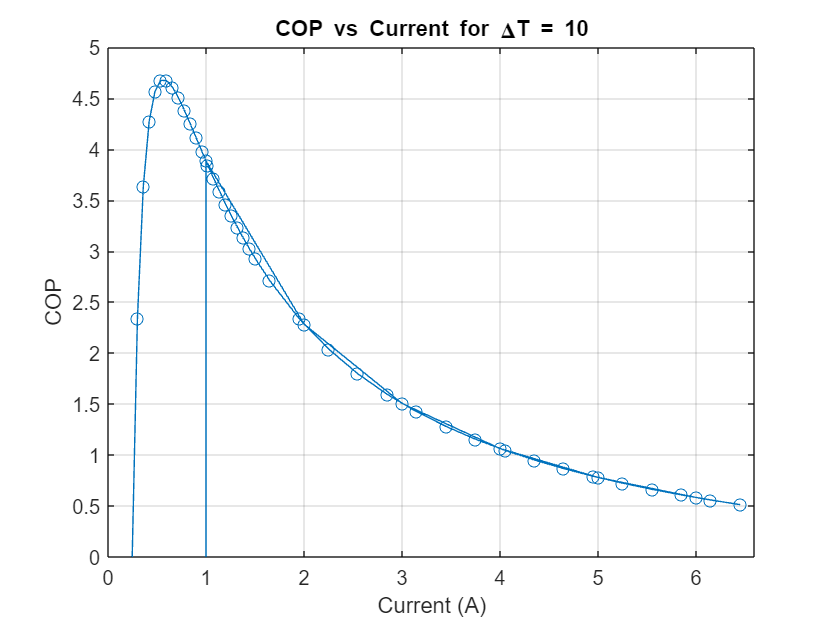

% Filter the data for DeltaT_C = 10
filteredData = data50(data50.DeltaT_C == 10, :);

% Extract Current and COP values for the filtered data
current = filteredData.Current_A;
cop = filteredData.COP;

% Plot COP as a function of Current
figure;
plot(current, cop, 'o-'); % 'o-' adds markers and lines
xlabel('Current (A)');
ylabel('COP');
title('COP vs Current for \DeltaT = 10');
xlim(curr_lim);
ylim(COP_lim);
grid on;

# Input Voltage

#### Voltage vs DeltaT 4every Current

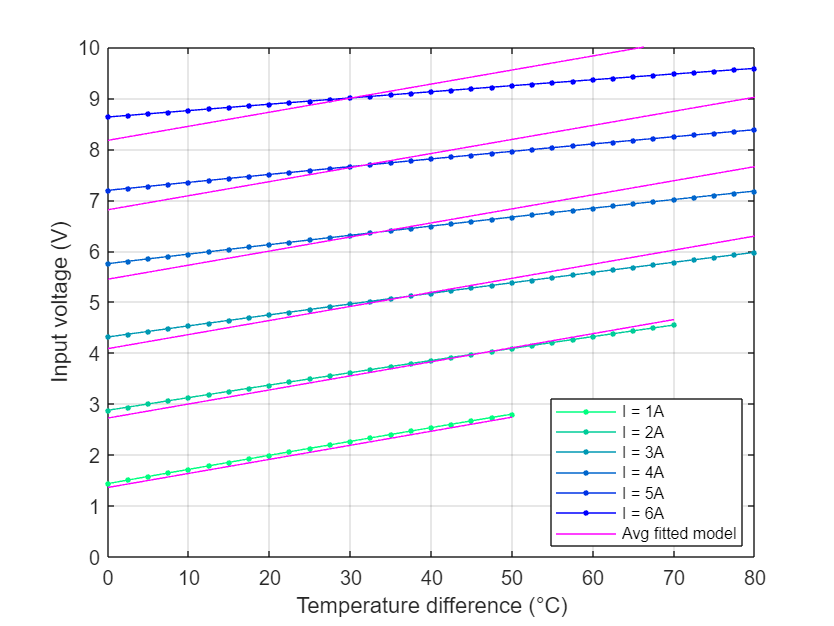

x_limits = deltaT_lim;
y_limits = voltage_lim;

figure
hold on

for i = 1:curr_len
    mask = data50.Current_A == curr(i) & data50.Th_C == T_hot; % working also with °C
    x2plot = data50.DeltaT_C(mask);
    y2plot = data50.Voltage_V(mask);

    p = plot(x2plot, y2plot);
    p.DisplayName = legend_dict(headers_keys{4}) + curr_str(i) + units_dict(headers_keys{4});
    p.LineStyle = '-';
    p.Marker = '.';
    p.Color = curr_colormap(i,:);
    p.MarkerSize = 8;

    y_param = voltage_fun(curr(i), x2plot);

    p_param = plot(x2plot, y_param);
    p_param.HandleVisibility = 'off';
    p_param.LineStyle = '-';
    p_param.Color = 'm';

end

p_param.HandleVisibility = 'on';
p_param.DisplayName = 'Avg fitted model';

xlabel(label_dict(headers_keys{3}));
ylabel(label_dict(headers_keys{2}));
xlim(x_limits);
ylim(y_limits);
lg = legend('Location','best');
lg.FontSize = 8;
% title(label_dict(headers_keys{1}) + ": " + T_hot_str(1) + units_dict(headers_keys{1}));
grid on
box on

hold off

# Heat removed from cold side Q_in or Q_c

#### Q_c vs DeltaT 4every Current

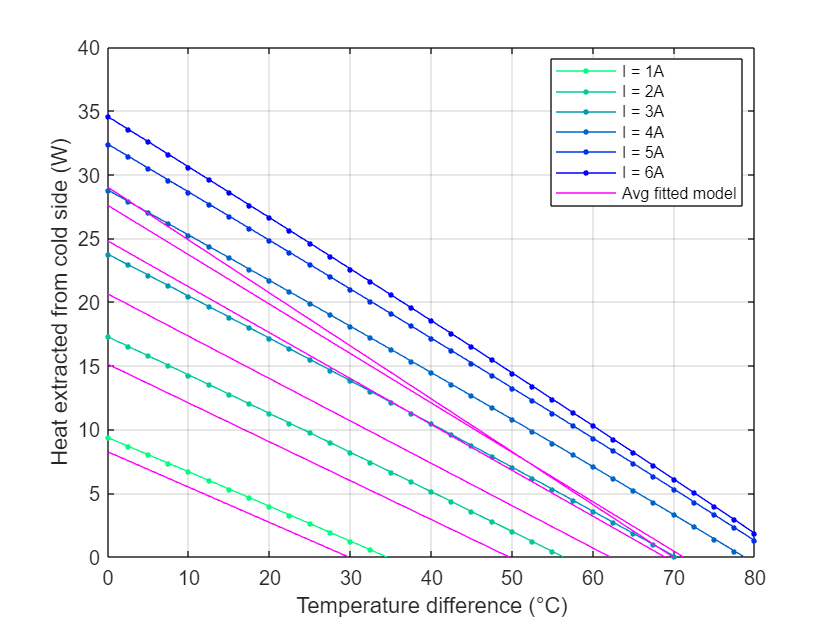

x_limits = deltaT_lim;
y_limits = Q_c_lim;

figure
hold on

for i = 1:curr_len
    mask = data50.Current_A == curr(i) & data50.Th_C == T_hot;
    x2plot = data50.DeltaT_C(mask);
    y2plot = data50.Qremoved_W(mask);

    % Sort x and y values
    sorted2plot = sortrows([x2plot, y2plot], 1);
    x2plot = sorted2plot(:, 1);
    y2plot = sorted2plot(:, 2);

    p = plot(x2plot, y2plot);
    p.DisplayName = legend_dict(headers_keys{4}) + curr_str(i) + units_dict(headers_keys{4});
    p.LineStyle = '-';
    p.Marker = '.';
    p.Color = curr_colormap(i,:);
    p.MarkerSize = 8;

    y_param = Q_removed_fun(curr(i), x2plot, T_hot_K);

    p_param = plot(x2plot, y_param);
    p_param.HandleVisibility = 'off';
    p_param.LineStyle = '-';
    p_param.Color = 'm';

end
% For the legend
% p_pred.HandleVisibility = 'on';
% p_pred.DisplayName = 'Fitted model';

p_param.HandleVisibility = 'on';
p_param.DisplayName = 'Avg fitted model';

xlabel(label_dict(headers_keys{3}));
ylabel(label_dict(headers_keys{5}));
xlim(x_limits);
ylim(y_limits);
lg = legend('Location','best');
lg.FontSize = 8;
% title(label_dict(headers_keys{1}) + ": " + T_hot_str + units_dict(headers_keys{1}));
grid on
box on

hold off

# Heat supplied to hot side Q_out or Q_h

#### Q_h vs DeltaT 4every Current

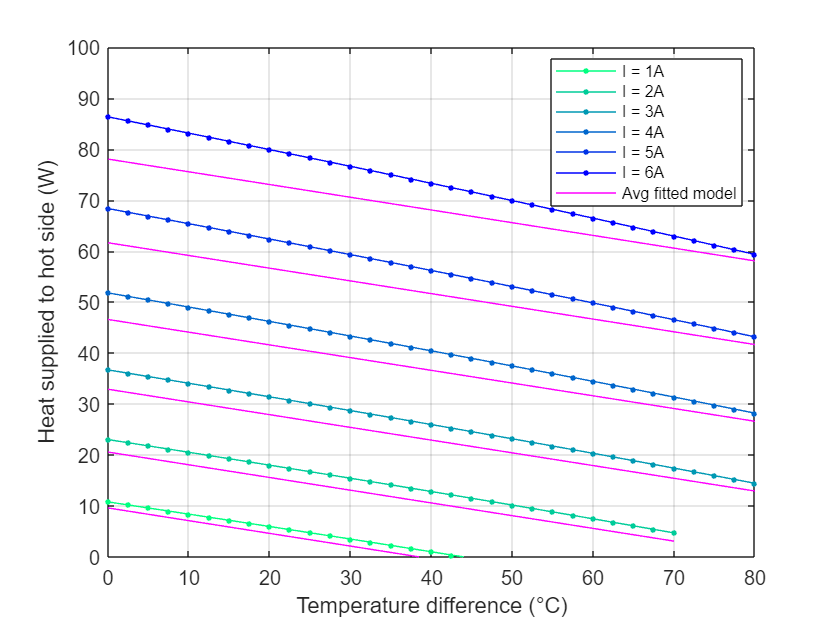

x_limits = deltaT_lim;
y_limits = Q_h_lim;

for j = 1:T_hot_len
    figure
    hold on
    
    for i = 1:curr_len
        mask = data50.Current_A == curr(i) & data50.Th_C == T_hot(j);
        x2plot = data50.DeltaT_C(mask);
        y2plot = data50.Qwaste_W(mask);

        % Sort x and y values
        sorted2plot = sortrows([x2plot, y2plot], 1);
        x2plot = sorted2plot(:, 1);
        y2plot = sorted2plot(:, 2);
    
        p = plot(x2plot, y2plot);
        p.DisplayName = legend_dict(headers_keys{4}) + curr_str(i) + units_dict(headers_keys{4});
        p.LineStyle = '-';
        p.Marker = '.';
        p.Color = curr_colormap(i,:);
        p.MarkerSize = 8;

        y_param = Q_waste_fun(curr(i), x2plot, T_hot_K(j));

        p_param = plot(x2plot, y_param);
        p_param.HandleVisibility = 'off';
        p_param.LineStyle = '-';
        p_param.Color = 'm';

    end

    p_param.HandleVisibility = 'on';
    p_param.DisplayName = 'Avg fitted model';
    
    xlabel(label_dict(headers_keys{3}));
    ylabel(label_dict(headers_keys{6}));
    xlim(x_limits);
    ylim(y_limits);
    lg = legend('Location','best');
    lg.FontSize = 8;
    % title(label_dict(headers_keys{1}) + ": " + T_hot_str(j) + units_dict(headers_keys{1}));
    grid on
    box on
    
    hold off
end

# COP

#### COP vs Current 4every DeltaT

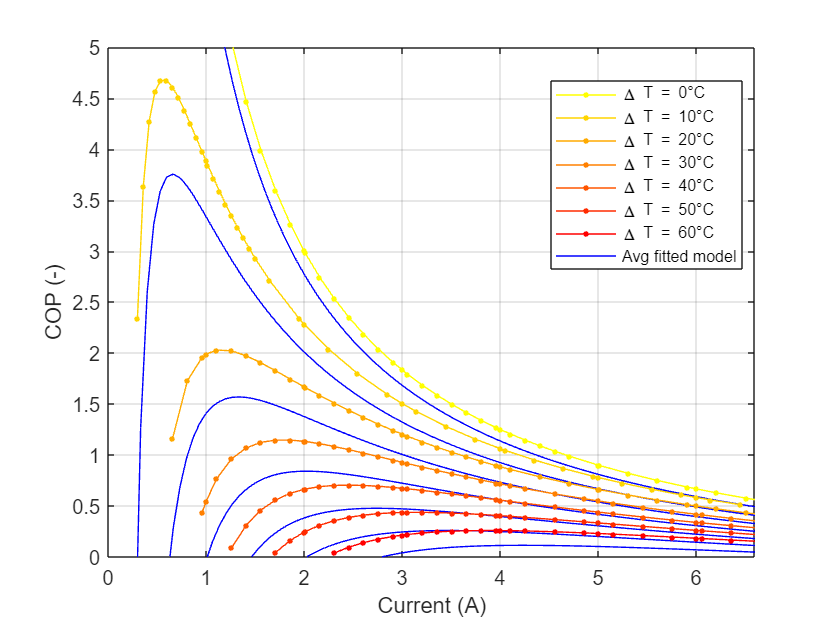

x_limits = curr_lim;
y_limits = COP_lim;

x2plot2 = linspace(curr_lim(1), curr_lim(2), 100);

figure
hold on

for i = 1:deltaT_len
    mask = data50.DeltaT_C == deltaT(i) & data50.Th_C == T_hot; % working also with °C
    x2plot = data50.Current_A(mask);
    y2plot = data50.COP(mask);

    % Sort x and y values
    sorted2plot = sortrows([x2plot, y2plot], 1);
    x2plot = sorted2plot(:, 1);
    y2plot = sorted2plot(:, 2);

    % Filter wrong values
    filter_mask = y2plot <= 10 & y2plot >= 0;
    x2plot = x2plot(filter_mask);
    y2plot = y2plot(filter_mask);

    p = plot(x2plot, y2plot);
    p.DisplayName = legend_dict(headers_keys{3}) + deltaT_str(i) + units_dict(headers_keys{3});
    p.LineStyle = '-';
    p.Marker = '.';
    p.Color = deltaT_colormap(i,:);
    p.MarkerSize = 8;

    U = voltage_fun(x2plot2, deltaT(i));
    P = x2plot2.*U;
    Q_c = Q_removed_fun(x2plot2, deltaT(i), T_hot_K);

    y_param = COP_fun(Q_c,P);

    p_param = plot(x2plot2, y_param);
    p_param.HandleVisibility = 'off';
    p_param.LineStyle = '-';
    p_param.Color = 'b';

end

p_param.HandleVisibility = 'on';
p_param.DisplayName = 'Avg fitted model';

xlabel(label_dict(headers_keys{4}));
ylabel(label_dict(headers_keys{7}));
xlim(x_limits);
ylim(y_limits);
lg = legend('Location','best');
lg.FontSize = 8;
% title(label_dict(headers_keys{1}) + ": " + T_hot_str(1) + units_dict(headers_keys{1}));
grid on
box on

hold off

# Fitting like in the Datasheet (ds)

#### 4 Subplots

xxx = linspace(0,6,100);
yyy = COP_fun(U, Q_c);
